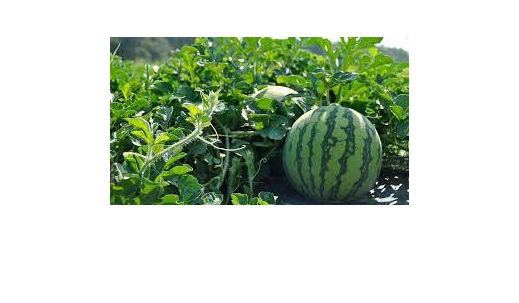

clear,clc;close all;
I = imread("watermelon-imgs/melon1.jpeg");
imshow(I)

h_mask_1 = hue_mask(I, 0.1, 0.55);

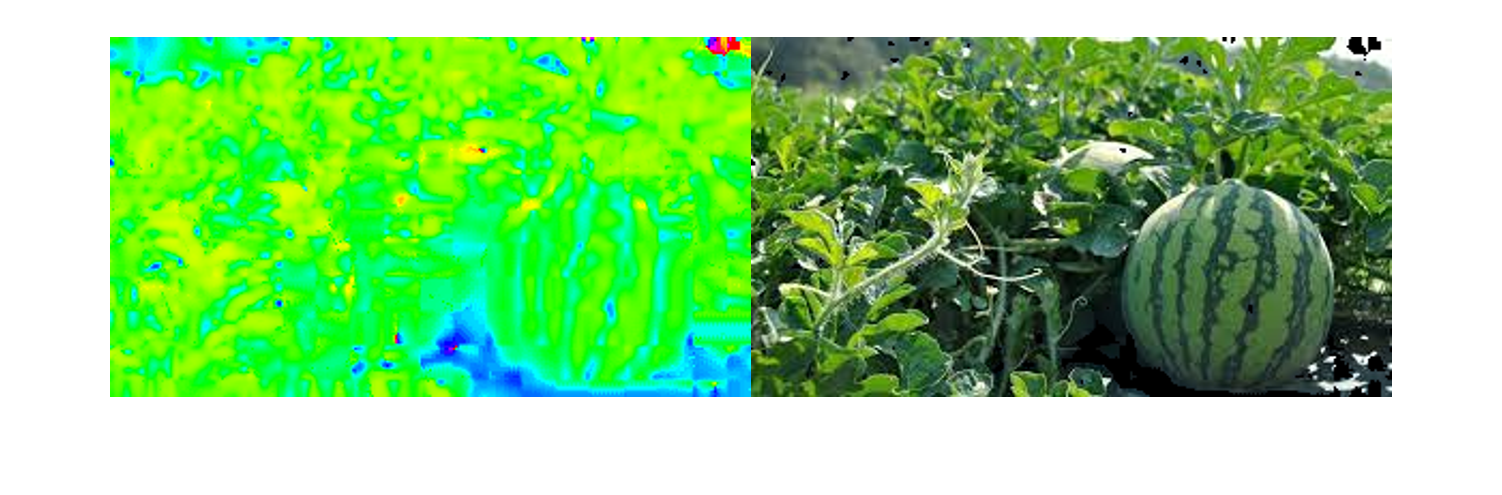

% view the hue mask
h_mask = uint8(repmat(h_mask_1, [1, 1, 3]));
hue_masked_img = I.*h_mask;
montage(cat(4, rgb2hue(I)*255, hue_masked_img))